
close all; clear;
%	Approximated based on hardware (DJI F-450 frame w/ 10in propellers) 
l = 0.23;
g = 9.81;
Kt = 0.02;
mass = 0.025;
Ixx = 4e-3;
Iyy = 4e-3;
Izz = 7e-3;
Ib = diag([Ixx Iyy Izz]);
d = -1e-3 * diag([1 1 1.75]);

RUFOUS_N_INPUTS = 4;			% number of inputs
RUFOUS_N_STATES = 4;			% number of states 4 (vectors)
RUFOUS_STATE_DIM = 3;			% dimension of each state


z = [0; 0; 1];
Z = [z z z z];
Xo = [0; 0; 0];
I = eye(RUFOUS_STATE_DIM);
O = zeros(RUFOUS_STATE_DIM, RUFOUS_STATE_DIM);

tau_k = [1  0 -1  0;
	     0 -1  0  1;
		-1  1 -1  1];

A = [O I O O;						% block size (state_dim, state_dim)
	 O O O O;
	 O O O I;
	 O O O O];

O = zeros(RUFOUS_STATE_DIM, RUFOUS_N_INPUTS);

B = Kt *[O; Z; O; l * tau_k];		% block size (state_dim, n_inputs) ignore non-controlled forces

C = eye(RUFOUS_N_STATES * RUFOUS_STATE_DIM);
D = 0;

G = ss(A, B, C, D);

20 states removed.


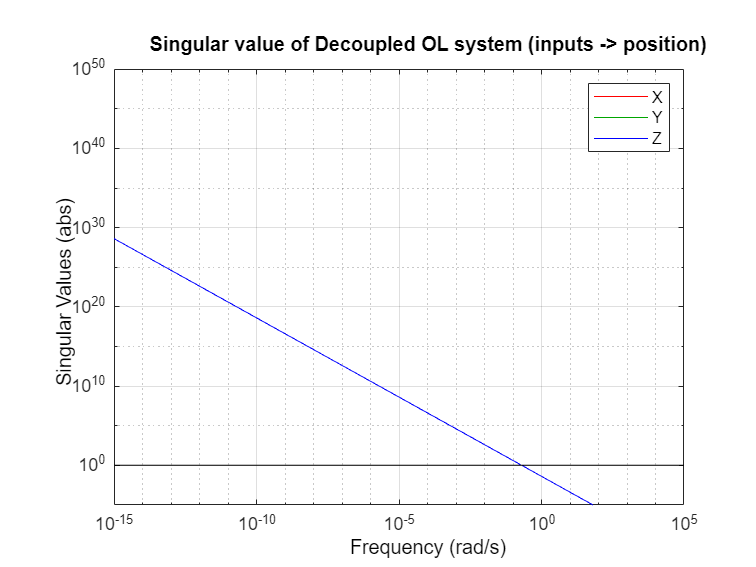

mag_range = [1e-5 1e50];
freq_range = [1e-15 1e5];

figure, hold on, grid minor
h = sigmaplot(G(1, :), 'r', G(2, :), 'g', G(3, :), 'b');
setoptions(h, 'MagUnits', 'abs', 'Xlim', freq_range, 'Ylim', mag_range)
plot(freq_range, [1, 1], 'k');
title("Singular value of Decoupled OL system (inputs -> position)")
legend("X", "Y", "Z")

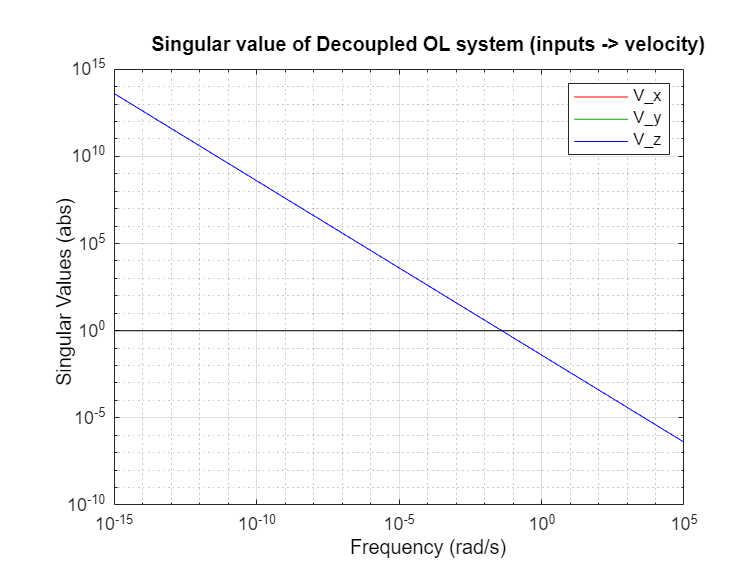


figure, hold on, grid minor
h = sigmaplot(G(4, :), 'r', G(5, :), 'g', G(6, :), 'b');
setoptions(h, 'MagUnits', 'abs', 'Xlim', freq_range)
plot(freq_range, [1, 1], 'k');
title("Singular value of Decoupled OL system (inputs -> velocity)")
legend("V_x", "V_y", "V_z")

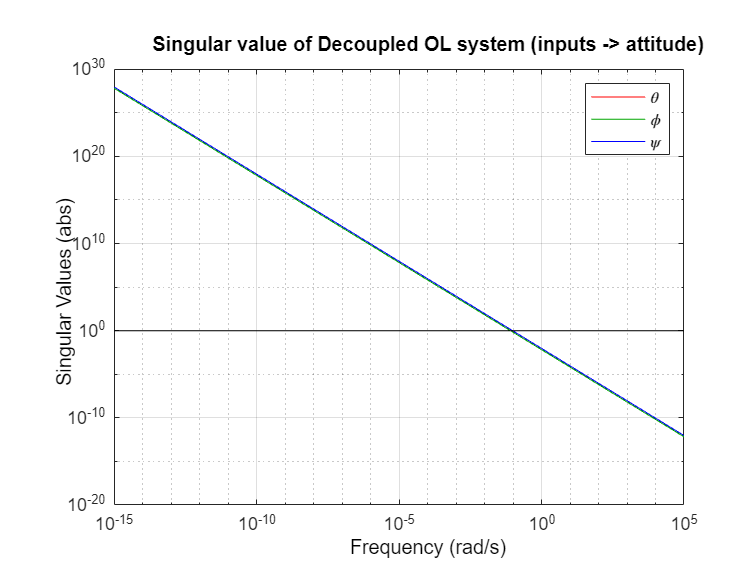


figure, hold on, grid minor
h = sigmaplot(G(7, :), 'r', G(8, :), 'g', G(9, :), 'b');
setoptions(h, 'MagUnits', 'abs', 'Xlim', freq_range)
plot(freq_range, [1, 1], 'k');
title("Singular value of Decoupled OL system (inputs -> attitude)")
legend("\theta", "\phi", "\psi")

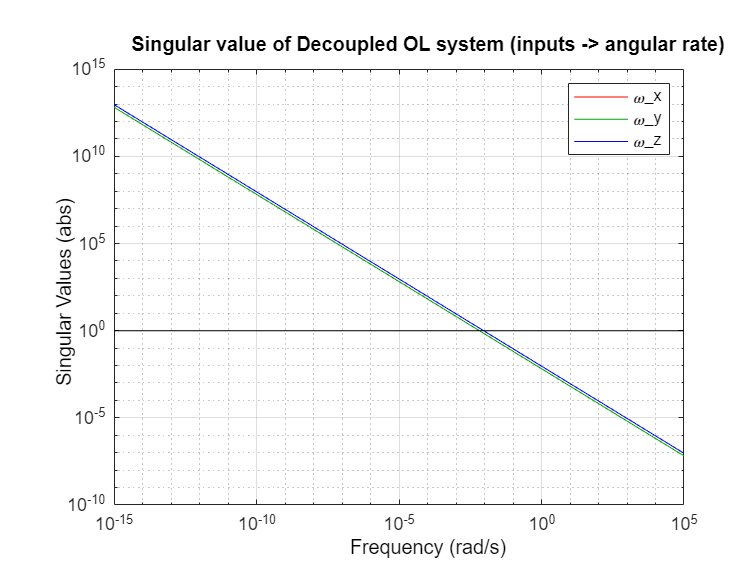

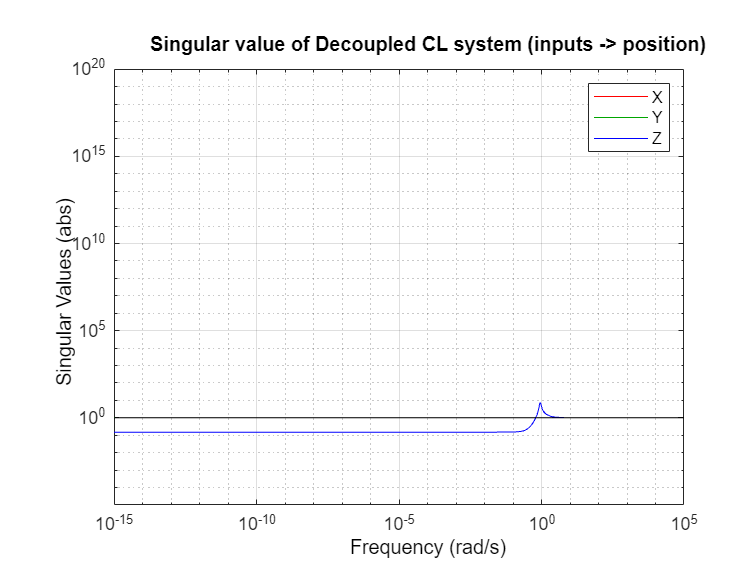

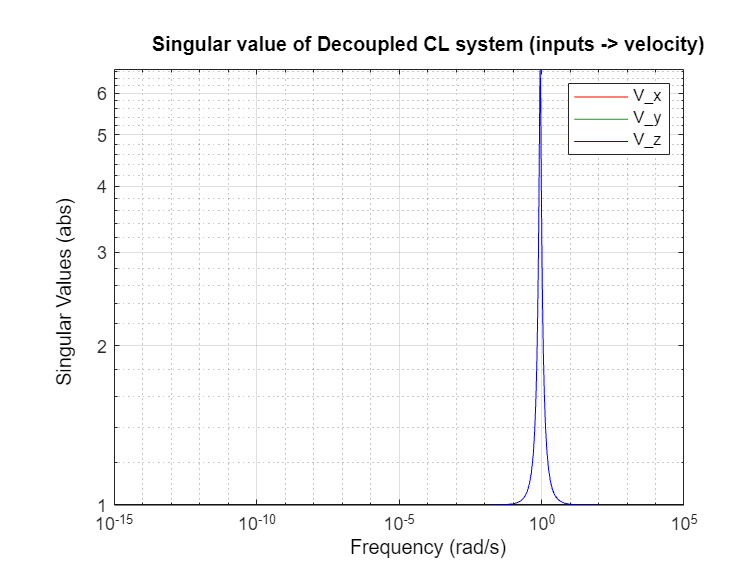

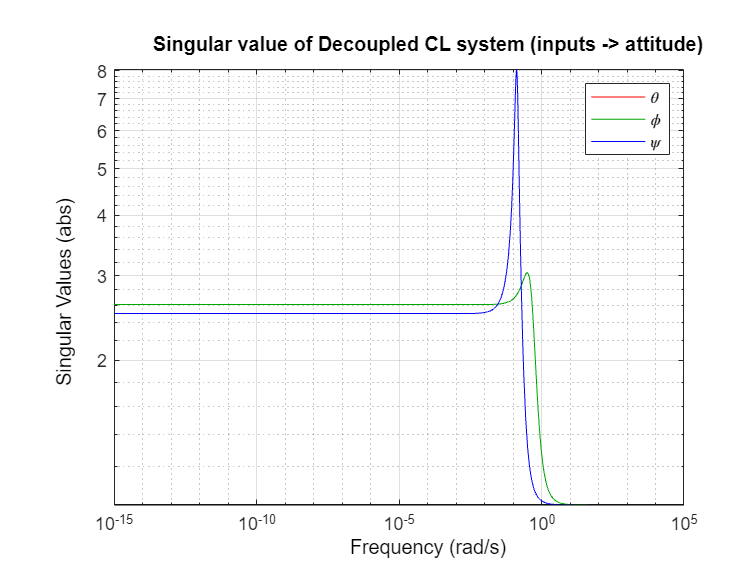

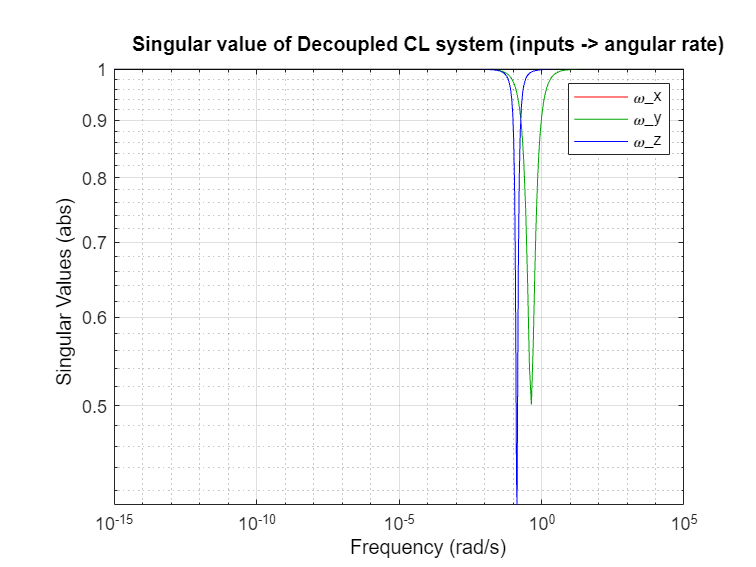


figure, hold on, grid minor
h = sigmaplot(G(10, :), 'r', G(11, :), 'g', G(12, :), 'b');
setoptions(h, 'MagUnits', 'abs', 'Xlim', freq_range)
plot(freq_range, [1, 1], 'k');
title("Singular value of Decoupled OL system (inputs -> angular rate)")
legend("\omega_x", "\omega_y", "\omega_z")

mag_range = [1e-2 1e4];
freq_range = [1e-10 1e3];

[Kref, Kfb, ~] = Rufous_og_controller(Kt, mass, g, [0; 0; 0], 40, 75, 0.1, 1, 50);
L = G * Kfb * Kref;
S = 1 / (eye(12) + L);
T = minreal(L * S);

28 states removed.



WI = makeweight(0.01, [1, 1], 10);

Hinf_norm_s = norm(S, 'inf')

Hinf_norm_s = 8.4403

Hinf_norm_t = norm(T, 'inf')

Hinf_norm_t = 8.4981

Hinf_norm_n11 = norm(WI * T, 'inf')

Hinf_norm_n11 = 1.4409

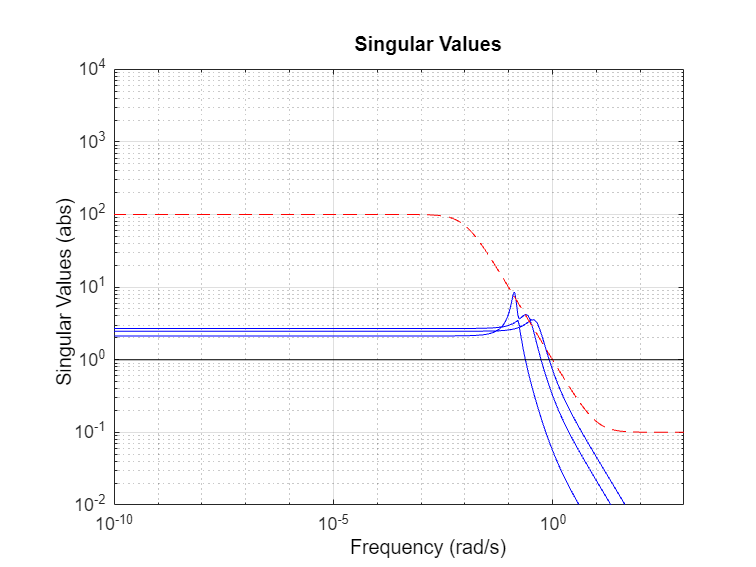


figure, hold on
h = sigmaplot(T, 'b', WI^-1, 'r--');
plot(freq_range, [1, 1], 'k');
setoptions(h, 'MagUnits', 'abs', 'Xlim', freq_range, 'Ylim', mag_range);

title("Nonlinear control law tuned by hand")